% SIMULERING AF SYSTEM
% 7 mikrofoner får et input a 1, 3, 10 kHz
% deres input er justeret efter position i array
% 3 ULAer med 3 mikrofoninput i hver 
% DAS på hver ULA - kræver fractional delay
% Frekvensfiltrering før eller efter DAS??
% Sum outputs
% PSD

clc
clear
close all
% Change DAS parameters in DAS.mlx
load('DASParams.mat')

fs = 48e3;

%inputAng = 100 
steerAng % Main lobe steering direction from DAS.mlx

steerAng = 12.0100

c = 1496;
%micTimeOffsets = micArray.*cosd(inputAng)/c
 % inputSig = sin(2*pi*(t+micTimeOffsets')*1000) ...
 %     + sin(2*pi*(t+micTimeOffsets')*3000) ...
 %     + sin(2*pi*(t+micTimeOffsets')*10000);
%inputSig = sin(2*pi*(t+micTimeOffsets').*linspace(1,24e3,length(t)))
%inputSig = sin(2*pi*(t+micTimeOffsets').*randi(24e3,1,length(t)))
zeroPad = 100;
%inputSig = [zeros(7,zeroPad) inputSig zeros(7,zeroPad)];


% Time offset in samples
tauOffset1 = tauULA1*fs; % Mic 1, 4, 7
tauOffset2 = tauULA2*fs; % Mic 2, 4, 6
tauOffset3 = tauULA3*fs; % Mic 3, 4, 5

% Fractional delays TBI

cfULA1 = 1700;
cfULA2 = [cfULA1 4000];
cfULA3 = cfULA2(2);

FIRULA1 = makeFIR(cfULA1, 100, fs, 'low');
FIRULA2 = makeFIR(cfULA2, 100, fs, 'bandpass');
FIRULA3 = makeFIR(cfULA3, 100, fs, 'high');
% freqz(FIRULA1,1,1024,fs);
% hold on
% freqz(FIRULA2,1,1024,fs);
% freqz(FIRULA3,1,1024,fs);
% hold off

inputAng = linspace(1,179,30);
freqs = linspace(0, 24e3, 241);
freqs(1) = 20;
freqs(end) = 24e3-20;
t = 0:1/fs:0.1;
magRatio = zeros(length(inputAng),length(freqs));

f = waitbar(0,'Starting...','Name','Simulating DAS',...
    'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');

for ang = 1:length(inputAng)
    micTimeOffsets = micArray.*cosd(inputAng(ang))/c;
    for freq = 1:length(freqs)
        inputSig = sin(2*pi*(t+micTimeOffsets')*freqs(freq));

        % Filter inputs 
        inputSigULA1 = filter(FIRULA1,1,inputSig,[],2);
        inputSigULA1 = [zeros(7,zeroPad) inputSigULA1 zeros(7,zeroPad)];
        inputSigULA2 = filter(FIRULA2,1,inputSig,[],2);
        inputSigULA2 = [zeros(7,zeroPad) inputSigULA2 zeros(7,zeroPad)];
        inputSigULA3 = filter(FIRULA3,1,inputSig,[],2);
        inputSigULA3 = [zeros(7,zeroPad) inputSigULA3 zeros(7,zeroPad)];
        
        % Output of each ULA
        ULA1Sum = inputSigULA1(1,zeroPad+round(tauOffset1(1)):end-1-zeroPad-round(tauOffset1(1)))...
            + inputSigULA1(4,zeroPad+round(tauOffset1(2)):end-1-zeroPad+round(tauOffset1(2))) ...
            + inputSigULA1(7,zeroPad+round(tauOffset1(3)):end-1-zeroPad+round(tauOffset1(3)));
        ULA1Sum = ULA1Sum * 1/3;
        
        ULA2Sum = inputSigULA2(2,zeroPad+round(tauOffset2(1)):end-1-zeroPad-round(tauOffset2(1)))...
            + inputSigULA2(4,zeroPad+round(tauOffset2(2)):end-1-zeroPad+round(tauOffset2(2))) ...
            + inputSigULA2(6,zeroPad+round(tauOffset2(3)):end-1-zeroPad+round(tauOffset2(3)));
        ULA2Sum = ULA2Sum * 1/3;
        
        ULA3Sum = inputSigULA3(3,zeroPad+round(tauOffset3(1)):end-1-zeroPad-round(tauOffset3(1)))...
            + inputSigULA3(4,zeroPad+round(tauOffset3(2)):end-1-zeroPad+round(tauOffset3(2))) ...
            + inputSigULA3(5,zeroPad+round(tauOffset3(3)):end-1-zeroPad+round(tauOffset3(3)));
        ULA3Sum = ULA3Sum * 1/3;
        
        arrayOutput = (ULA1Sum + ULA2Sum + ULA3Sum);
        %magRatio(ang,freq) = mean(arrayOutput.^2)/mean(sum(inputSig.^2,1))';
        magRatio(ang,freq) = mean(arrayOutput.^2)/mean(mean(inputSig.^2,2))';

    end
    setappdata(f,'canceling',0);
    waitbar(ang/length(inputAng),f,sprintf('%d°',inputAng(ang)))
end
delete(f)


## Plot BPs and DF

magRatiodB = 10*log10(magRatio)

magRatiodB =     0.0147    0.0024   -0.0258   -0.0487   -0.0560   -0.0540   -0.0515   -0.0456   -0.0281   -0.0066   -0.0185   -0.1275   -0.4136   -0.9702   -1.9100   -3.3722   -5.5043   -8.2300  -10.0240   -8.5341   -5.8839   -3.7631   -2.2885   -1.3143   -0.7021   -0.3443   -0.1578   -0.0777   -0.0534   -0.0477   -0.0345    0.0020    0.0694    0.1669    0.2859    0.4103    0.5182    0.5850    0.5906    0.5262    0.4008    0.2410    0.0831   -0.0418   -0.1202   -0.1580   -0.1710   -0.1743   -0.1760   -0.1781
    0.0147    0.0024   -0.0257   -0.0482   -0.0549   -0.0524   -0.0494   -0.0430   -0.0245   -0.0019   -0.0125   -0.1203   -0.4051   -0.9599   -1.8975   -3.3570   -5.4867   -8.2153  -10.0313   -8.5571   -5.9024   -3.7756   -2.2965   -1.3191   -0.7048   -0.3456   -0.1584   -0.0780   -0.0537   -0.0478   -0.0346    0.0021    0.0694    0.1667    0.2855    0.4098    0.5175    0.5844    0.5899    0.5252    0.3994    0.2391    0.0806   -0.0448   -0.1235   -0.1614   -0.1745   -0.1779   -0.

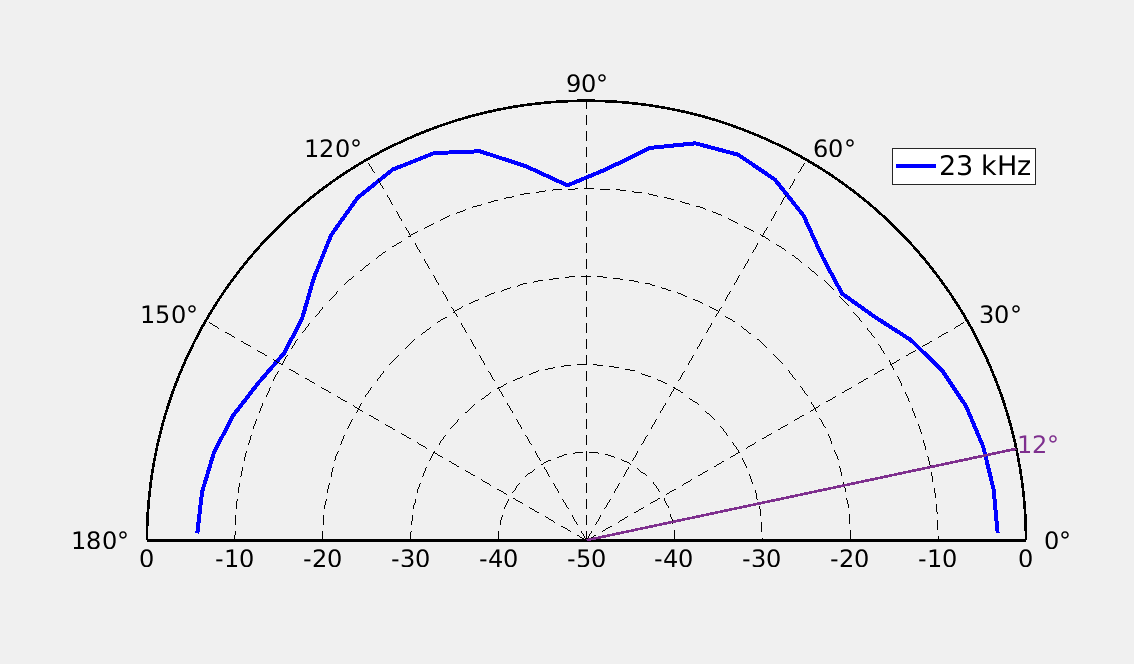

indexHz = find(freqs==23e3); % Find design frequency in sweep list
plotVisibility = 'on';

figure(1)
set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
          'OuterPosition', [0 0 30 20]) %21/2-2*2
circPlot(freqs(indexHz), inputAng*pi/180, magRatiodB(:,indexHz)', steerAng)

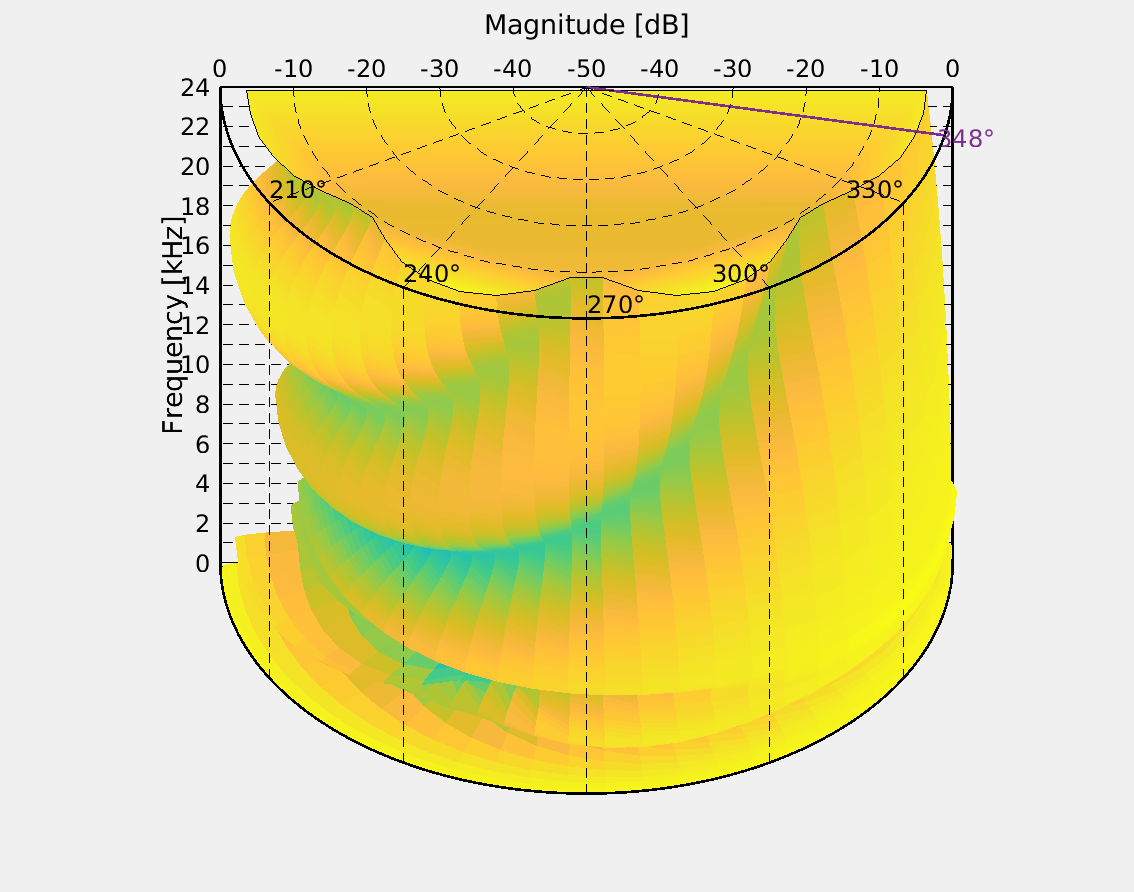


figure(2)
set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
          'OuterPosition', [0 0 30 30])
cylindricalPlot(freqs, inputAng*pi/180, magRatiodB', steerAng)

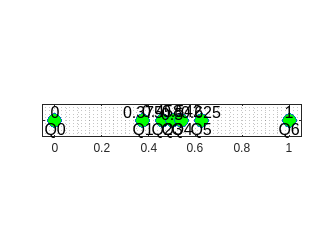


figure(3)
plot(micArray, zeros(length(micArray),1), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'g')
hold on
%text(micArray, zeros(length(micArray),1)+0.5+(-1).^(0:length(micArray)-1)'*0.12, string(round(micArray,3)), 'HorizontalAlignment', 'center', 'FontSize', 12)
text(micArray, zeros(length(micArray),1)+0.5+[0 0 0.12 -0.12 0.12 0 0]', string(round(micArray,3)), 'HorizontalAlignment', 'center', 'FontSize', 12)
text(micArray, zeros(length(micArray),1)-0.5, 'Q' + string(0:length(micArray)-1), 'HorizontalAlignment', 'center', 'FontSize', 12)
pbaspect([8 1 1])
set(gca,'YTickLabel',{' '})
xlim([-0.05 1.05])
grid minor
hold off

## Generate .c and .h files

% Check for "length should be divided by 4 and aligned to 16"
% for f = ["FIRULA1" "FIRULA2" "FIRULA3"]
%     if mod(length(eval('f')),16) ~= 0
%         %padLength = bitand(int(length(FIRULA1) + 3), bitcmp(3))
%         %padLength = 4 * ceil((length(FIRULA1) + 3) / 4);
%         padLength = 16-mod(length(eval('f')),16)
%         eval('f') = zeros(length(eval('f'))+padLength,1)'
%         %mod(length(eval('f'))+padLength,16)
%     end
% end

% if mod(length(FIRULA1),16) ~= 0
%     padLength = 16-mod(length(FIRULA1),16)
%     FIRULA1 = [FIRULA1 zeros(1,padLength)]
% end
% 
% if mod(length(FIRULA2),16) ~= 0
%     padLength = 16-mod(length(FIRULA2),16)
%     FIRULA2 = [FIRULA2 zeros(1,padLength)]
% end
% 
% if mod(length(FIRULA3),16) ~= 0
%     padLength = 16-mod(length(FIRULA3),16)
%     FIRULA3 = [FIRULA3 zeros(1,padLength)]
% end

% Get the dimensions of the matrix
FIR1Length = length(FIRULA1);
FIR2Length = length(FIRULA2);
FIR3Length = length(FIRULA3);

% Open the header file for writing
fid_h = fopen('DAS/main/FIRWeights.h', 'w');

% Write the header file contents
%fprintf(fid_h, '#include <complex.h>\n\n');
fprintf(fid_h, '#ifndef FIRWEIGHTS_H\n');
fprintf(fid_h, '#define FIRWEIGHTS\n\n');

fprintf(fid_h, '#define FIR1LENGTH %d\n', FIR1Length);
fprintf(fid_h, '#define FIR2LENGTH %d\n', FIR2Length);
fprintf(fid_h, '#define FIR3LENGTH %d\n\n', FIR3Length);
fprintf(fid_h, 'static __attribute__((aligned(16))) float FIR1WEIGHTS[FIR1LENGTH] = \n\t{');
for r = 1:FIR1Length
    fprintf(fid_h, '%f', cast(FIRULA1(r),"single"));
    if r < FIR1Length
        fprintf(fid_h, ',');
    end
end
fprintf(fid_h, '};\n\n');

fprintf(fid_h, 'static __attribute__((aligned(16))) float FIR2WEIGHTS[FIR2LENGTH] = \n\t{');
for r = 1:FIR2Length
    fprintf(fid_h, '%f', cast(FIRULA2(r),"single"));
    if r < FIR2Length
        fprintf(fid_h, ',');
    end
end
fprintf(fid_h, '};\n\n');


fprintf(fid_h, 'static __attribute__((aligned(16))) float FIR3WEIGHTS[FIR3LENGTH] = \n\t{');
for r = 1:FIR3Length
    fprintf(fid_h, '%f', cast(FIRULA3(r),"single"));
    if r < FIR3Length
        fprintf(fid_h, ',');
    end
end
fprintf(fid_h, '};\n\n');

fprintf(fid_h, '#endif // FIRWEIGHTS_H\n');

% Close the header file
fclose(fid_h);

disp('Header file generated successfully.');

Header file generated successfully.


function coeffs_adjusted = makeFIR(Fc, order, fs, type)
if ~exist('type', 'var') 
    coeffs = fir1(order,2*Fc/fs);
else 
    coeffs = fir1(order,2*Fc/fs, type);
end 
[mag, freq] = freqz(coeffs,1,1024,fs);
magdB = 20*log10(abs(mag));
if length(Fc) == 1
    [~, minIndex] = min(abs(magdB + 3));
    Fc_3dB = freq(minIndex);
    Fc_adjusted = Fc * (Fc/Fc_3dB);
    coeffs_adjusted = fir1(order, 2*Fc_adjusted/fs, type);
elseif length(Fc) == 2
    %[~, minIndexLow] = min(abs(magdB + 3));
    minIndexLow = find(abs(magdB)<3,1);
    minIndexHigh = find(abs(magdB(minIndexLow:end))>3,1) + minIndexLow;
    FcLow_3dB = freq(minIndexLow);
    FcHigh_3dB = freq(minIndexHigh);
    FcLow_adjusted = Fc(1) * (Fc(1)/FcLow_3dB);
    FcHigh_adjusted = Fc(2) * (Fc(2)/FcHigh_3dB);
    coeffs_adjusted = fir1(order, 2*[FcLow_adjusted FcHigh_adjusted]/fs, type);
else
    disp("nederen")
end
end